# Design Through Analysis

%% Licensing
%
% License:         BSD License
%                  cane Multiphysics default license: cane/license.txt
%
% Main authors:    Andreas Apostolatos
%
%% Script documentation
% 
% Task : Form-finding analysis for a four-point sail
%
% Date : 08.02.2020
%
%% Preamble
clear;
clc;
close all;

## Includes

path_prefix = '../../../../';
is_loaded = load_dependencies(path_prefix);

## CAD modelling via NURBS

% Global variables
Length = 20;
Width = Length;
Height = Length/2;

% Create the multipatch geometry
patchesCAD = load_fourPointSinglePatchCAD(Length, Width, Height);
num_patches = length(patchesCAD);

## Material and geometric constants

% Membrane
EYoung = 8e+8; % Young's modulus
nue = .4; % Poisson ratio
thickness = 1e-3; % lateral thickness
sigma0 = 3e+3; % prestress amplitude
prestress.voigtVector = [sigma0/thickness % prestress tensor in Voigt notation
                         sigma0/thickness
                         0];
density = 8050; % Material density
parameters = set_parametersMembrane(EYoung, nue, density, thickness, prestress);

% Cables
E = 1.6e+11; % Young's modulus of the cable
rho = 8300; % Material density
radiusCS = 12e-3/2; % Cross sectional radius
areaCS = pi*radiusCS^2; % Cross sectional area
prestress = 6e+4/areaCS; % Prestress
parametersCable = set_parametersCable(E, rho, areaCS, prestress);


## User Interface

% Case name
caseName = 'SinglePatchFourPointSail';

% Analysis type
analysis.type = 'isogeometricMembraneAnalysis';

% Define equation system solver
solve_LinearSystem = @solve_LinearSystemMatlabBackslashSolver;

% Define nonlinear analysis properties
propNLinearAnalysis.method = 'newtonRapshon'; % method
propNLinearAnalysis.noLoadSteps = 1; % Number of load steps
propNLinearAnalysis.eps = 1e-6; % Tolerance
propNLinearAnalysis.maxIter = 1e2; % Maximum number of iterations

% Integration properties
int.type = 'default';
intC.type = 'user';

% Graphics properties
graph.index = 1;
graph.postprocConfig = 'referenceCurrent'; % 'reference','current','referenceCurrent'
graph.resultant = 'displacement'; % 'displacement','strain','curvature','force','moment','shearForce'
graph.component = '2norm'; % 'x','y','z','2norm','1','2','12','1Principal','2Principal'

% Function handle to writing out the results
% writeOutput = @writeResults4Carat;
% writeOutput = @writeResults4GiD;
writeOutput = 'undefined';

% Postprocessing
propPostproc.resultant = {'displacement'};
propPostproc.computeResultant = {'computeDisplacement'};


## Refinement

num_xi = 10; % Number of knots to insert along xi
num_eta = 10; % Number of knots to insert along eta
dp = 1; % Increment polynomial order along xi
dq = 1; % Increment polynomial order along eta
patchesCAD{1} = refine_patchCAD(patchesCAD{1}, num_xi, num_eta, dp, dq, 'outputEnabled');

__________________________________________________________
##########################################################
Degree elevation for a B-Spline srface has been initiated 

Polynomial degree in xi-direction before elevation p = 1
Polynomial degree in xi-direction after elevation p = 2
Polynomial degree in eta-direction before elevation q = 1
Polynomial degree in eta-direction after elevation q = 2
__________________________________________________________

Degree elevation took 1.83e-02 seconds 

__________________Degree Elevation Ended__________________
##########################################################


________________________________________________________________
################################################################
Uniform Knot insertion for a B-Spline curve has been initiated 

Number of knots before knot insertion in xi-direction nxi = 6
Number of knots after knot insertion in xi-direction nxi = 16
Number of knots before knot insertion in eta-direction

## Boundary conditions

% Homogeneous Dirichlet boundary conditions
homDOFs = [];
propHomBC.noCnd = 4;
propHomBC.xiExtension = {[0 0] [1 1] [0 0] [1 1]};
propHomBC.etaExtension = {[0 0] [0 0] [1 1] [1 1]};
propHomBC.directions = {1:3 1:3 1:3 1:3};
homDOFs = set_homogeneousDirichletBoundaryConditions(homDOFs, patchesCAD{1}, propHomBC);

% Inhomogeneous Dirichlet boundary conditions
inhomDOFs = [];
valuesInhomDOFs = [];

% Weak homogeneous Dirichlet boundary conditions
weakDBC.noCnd = 0;

% Embedded cables
cables.No = 4;
cables.xiExtension = {[0 1] [0 1] [0 0] [1 1]};
cables.etaExtension = {[0 0] [1 1] [0 1] [0 1]};
cables.parameters = {parametersCable parametersCable parametersCable parametersCable};
cables.int.type = 'default';
cables.int.noGPs = 16;

% Neumann boundary conditions
NBC.noCnd = 0;

## Build the computational model for the form-finding analysis

BSplinePatches = cell(num_patches);
for i = 1:num_patches
    BSplinePatches{i} = fillUpPatch...
        (analysis,patchesCAD{i}.p,patchesCAD{i}.Xi,patchesCAD{i}.q,patchesCAD{i}.Eta,patchesCAD{i}.CP,patchesCAD{i}.isNURBS,...
        parameters,homDOFs,inhomDOFs,valuesInhomDOFs,weakDBC,cables,NBC,[],[],[],[],[],int);
    BSplinePatches{i}.FGamma = zeros(3*BSplinePatches{i}.noCPs,1);
end
connections.No = 0;

## Plot the distribution of the determinant of the geometric Jacobian

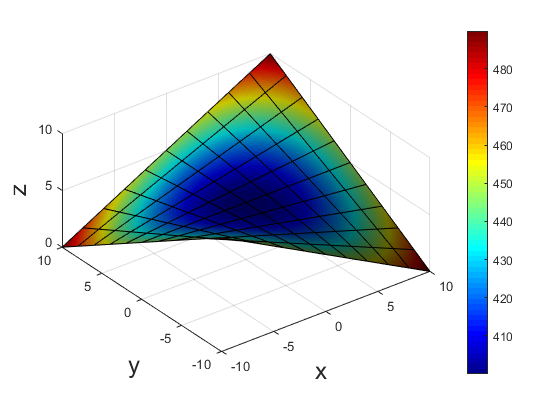

% Plot the distribution of the determinant of the geometrical Jacobian for the multipatch geometry
figure(graph.index)
for i = 1:num_patches
    plot_postprocBSplineSurfaceGeometricJacobian...
        (BSplinePatches{i}.p,BSplinePatches{i}.q,...
        BSplinePatches{i}.Xi,BSplinePatches{i}.Eta,...
        BSplinePatches{i}.CP,BSplinePatches{i}.isNURBS);
    hold on;
end
hold off;
shading interp;
colormap('jet');
camlight left;
lighting phong;
colorbar;
axis equal;

graph.index = graph.index + 1;

## Plot the geometry before form-finding

%% Plot the reference configuration for the multipatch geometry before the form-finding analysis
color = [217 218 219]/255;
% color = 'none';
graph.index = plot_referenceConfigurationIGAThinStructureMultipatches...
    (BSplinePatches,connections,color,graph,'outputEnabled');

_____________________________________________________
#####################################################
Plotting the reference configuration for a multipatch
isogeometric Kirchhoff-Love shell has been initiated
_____________________________________________________



Plotting the reference configuration took 2.47e-01 seconds 

________Plotting Reference Configuration Ended_______
#####################################################




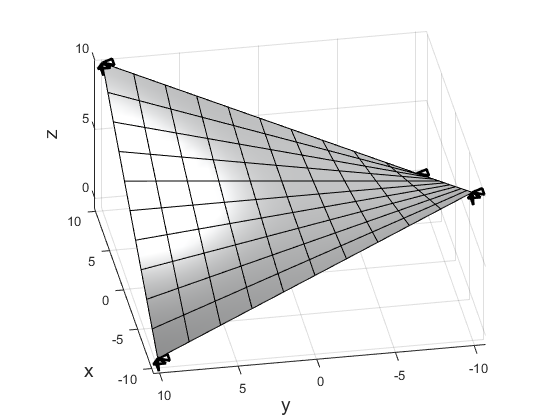

az = 260;
el = 30;
view(az,el);
camlight(30,70);
lighting phong;

## Perform a form finding analysis to find the shape of the membrane 

propFormFinding.tolerance = 1e-4;
propFormFinding.maxNoIter = 1e1;
patchesCAD_FoFi = cell(num_patches);
[patchesCAD_FoFi{1},CPHistory,resHistory,hasConverged,noIter] = ...
    solve_formFindingIGAMembrane(BSplinePatches{1},propFormFinding,...
    solve_LinearSystem,'outputEnabled');

__________________________________________________________________
##################################################################
Form Finding analysis for a membrane has been initiated 

Form finding iteration tolerance : 0.000100 
Maximum number of form finding iterations: 10 


__________________________________________________________________

		Looping over the form finding iterations
		----------------------------------------

		||delta_dHat|| = 1.524211e+01 at form-finding iteration No. 1 
		||delta_dHat|| = 1.071497e+01 at form-finding iteration No. 2 
		||delta_dHat|| = 2.595874e+00 at form-finding iteration No. 3 
		||delta_dHat|| = 1.006052e+00 at form-finding iteration No. 4 
		||delta_dHat|| = 4.601351e-01 at form-finding iteration No. 5 
		||delta_dHat|| = 2.321243e-01 at form-finding iteration No. 6 
		||delta_dHat|| = 1.245517e-01 at form-finding iteration No. 7 
		||delta_dHat|| = 6.953860e-02 at form-finding iteration No. 8 
		||delta_dHat|| = 3.983367e-02 at form

Form finding analysis took 3.38e+00 seconds 

___________________Form Finding Analysis Ended____________________
##################################################################




## Plot the geometry after form-finding

color = [217 218 219]/255; % 'none'
graph.index = plot_referenceConfigurationIGAThinStructureMultipatches...
    (patchesCAD_FoFi,connections,color,graph,'outputEnabled');

_____________________________________________________
#####################################################
Plotting the reference configuration for a multipatch
isogeometric Kirchhoff-Love shell has been initiated
_____________________________________________________



Plotting the reference configuration took 2.41e-01 seconds 

________Plotting Reference Configuration Ended_______
#####################################################




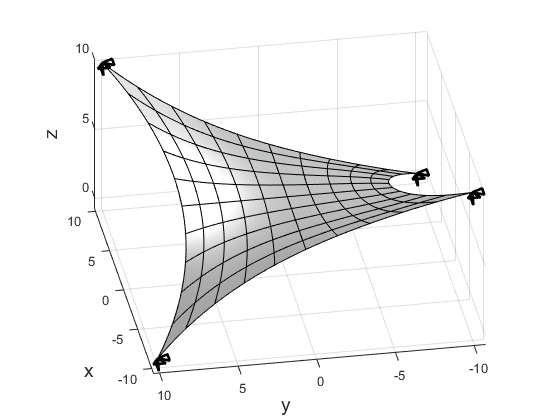

az = 260;
el = 30;
view(az,el);
camlight(30,70);
lighting phong;

## Build the computational model for the quasi nonlinear modal analysis

BSplinePatches = cell(num_patches);
for i = 1:num_patches
    BSplinePatches{i} = fillUpPatch...
        (analysis,patchesCAD_FoFi{i}.p,patchesCAD_FoFi{i}.Xi,patchesCAD_FoFi{i}.q,patchesCAD_FoFi{i}.Eta,patchesCAD_FoFi{i}.CP,patchesCAD_FoFi{i}.isNURBS,...
        parameters,homDOFs,inhomDOFs,valuesInhomDOFs,weakDBC,cables,NBC,[],[],[],[],[],int);
    BSplinePatches{i}.FGamma = zeros(3*BSplinePatches{i}.noCPs,1);
end
connections.No = 0;

## Perform quasi nonlinear modal analysis

num_eig = 5; % Number of eigenmode shapes to be computed
[eigenmodeShapes,naturalFrequencies,dHat] = solve_eigenmodeAnalysisIGAMembrane...
    (BSplinePatches{1},solve_LinearSystem,num_eig,propNLinearAnalysis,'outputEnabled');

_______________________________________________________________
###############################################################
Modal analysis for the isogeometric membrane has been initiated

Number of eigenfrequencies requested : 5

_______________________________________________________________

	>> Computing the constant matrices related to the application of weak Dirichlet boundary conditions
	>> Performing steady-state analysis to bring the structure in equilibrium
		Nonlinear method : newtonRapshon

		Load step 1/1 
		----------------

			Looping over the nonlinear iterations
			-------------------------------------

			||resVct|| = 1.100371e+02 at nonlinear iteration No. 1 
			||resVct|| = 7.472783e-03 at nonlinear iteration No. 2 
			||resVct|| = 4.207116e-08 at nonlinear iteration No. 3 

			Nonlinear iterations converged! 
 
 
	>> Computing the linear stiffness matrix of the structure
	>> Computing the mass matrix of the structure
	>> Solving the generalized eigenvalue probl

BSplinePatchesEq = BSplinePatches;
BSplinePatchesEq{1}.CP = computeDisplacedControlPointsForIGAKirchhoffLoveShell...
    (BSplinePatches{1}.CP,dHat);

## Plot the eigenmode shape

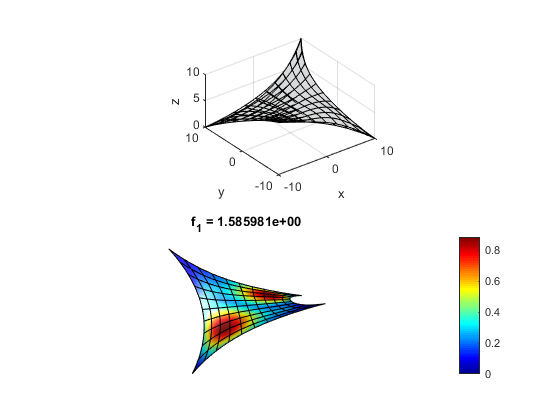

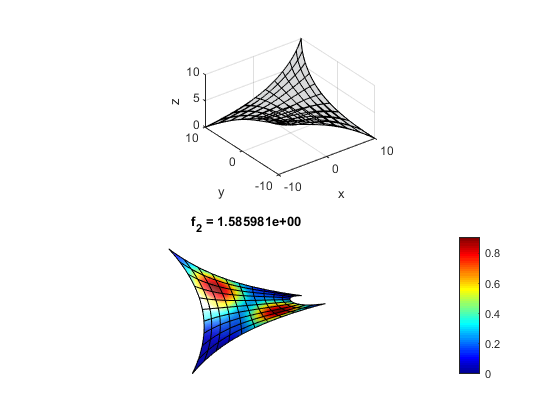

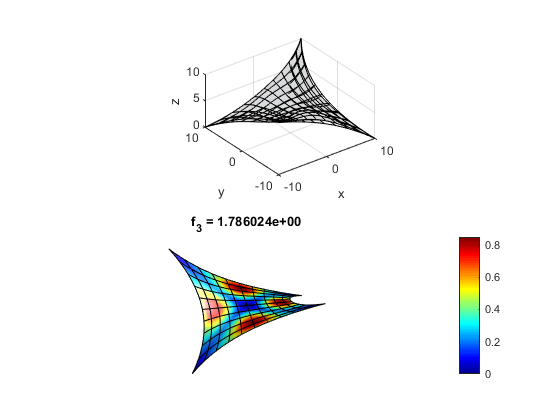

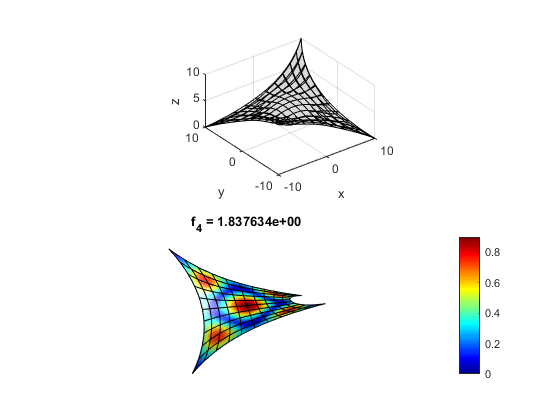

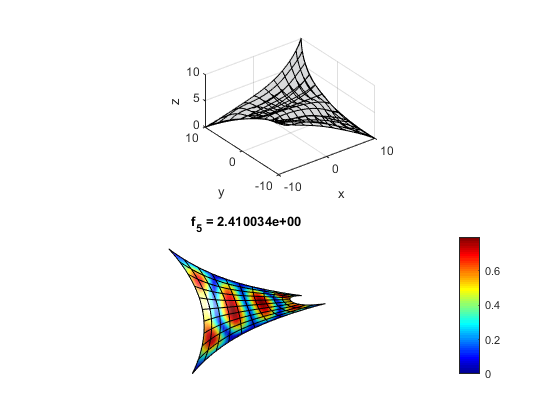

for i = 1:num_eig
    % Plot the displaced patch
    scalingFct = 20;
    noEigen = i;
    graph.index = plot_postprocIGAMembraneMultipatchesNLinear...
       (BSplinePatchesEq,scalingFct*eigenmodeShapes(:,noEigen),graph,'');
    az = 260;
    el = 30;
    view(az,el);
    camlight(30,70);
    lighting phong;
    axis off;
    title(sprintf('f_{%d} = %d',i,naturalFrequencies(i,1)));
end